clear all; clc
syms S(t) I(t) V(t) u rho beta delta c p
ode1 = diff(S)==u-rho*S-beta*S*V;
ode2 = diff(I)== beta*S*V -delta*I;
ode3 = diff(V)== p*I-c*V;
odes=[ode1;ode2;ode3]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}S\left(t\right)=u-\rho \,S\left(t\right)-\beta \,S\left(t\right)\,V\left(t\right)\\ \frac{\partial }{\partial t}\text{I}\left(t\right)=\beta \,S\left(t\right)\,V\left(t\right)-\delta \,\text{I}\left(t\right)\\ \frac{\partial }{\partial t}V\left(t\right)=p\,\text{I}\left(t\right)-c\,V\left(t\right) \end{array}\right)$$

vars=[S I V];

sympref('FloatingPointOutput',true);

domain=[0 1000];%rango numérico en el que se solucionará el sistema
modelName='siv';%nombre para el archivo de modelo
gsua_dataprep(odes,vars,domain,modelName);%consultamos el orden para introducir los parámetros

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccccccc} S\left(t\right) & \text{I}\left(t\right) & V\left(t\right) & \beta & c & \delta & p & \rho & u \end{array}\right)$$

nominal=[5e5 0 1 1.91e-7 8.02 1e-3 378 1e-3 500];
range=[5e5 5e5; 0 0;0.8 1.2; 1.52e-7 2.29e-7; 6.41 9.62;0.0008 0.0012;302.4 453.6;0.001 0.001; 400 600];
T = gsua_dataprep(odes,vars,domain,modelName,'range',range,'nominal',nominal)%generamos la tabla del sistema

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccccccc} S\left(t\right) & \text{I}\left(t\right) & V\left(t\right) & \beta & c & \delta & p & \rho & u \end{array}\right)$$

T = 6×2 table
                    Range            Nominal 
             ____________________    ________

    V0            0.8         1.2           1
    beta     1.52e-07    2.29e-07    1.91e-07
    c            6.41        9.62        8.02
    delta      0.0008      0.0012       0.001
    p           302.4       453.6         378
    u             400         600         500


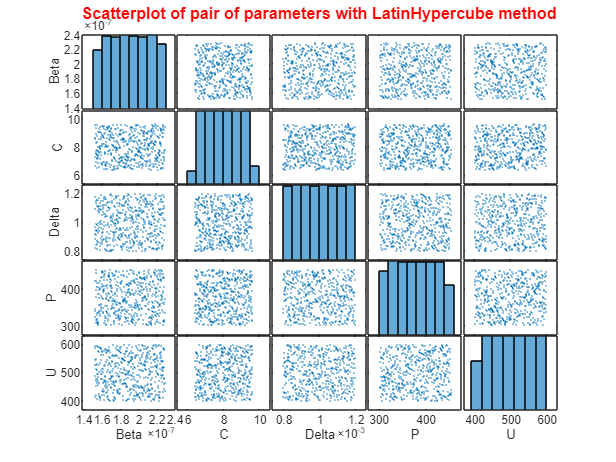

M = gsua_dmatrix(T, 500, 'Show', 'on');

T

T = 5×2 table
                    Range             Nominal 
             ____________________    _________

    Beta     1.52e-07    2.29e-07    1.905e-07
    C            6.41        9.62        8.015
    Delta      0.0008      0.0012        0.001
    P           302.4       453.6          378
    U             400         600          500


T.Properties.CustomProperties.output = 1;

Tsa = gsua_sa(M, T, 'parallel', true);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
Progress: 13%
Estimated processing time (h:m:s): 0:33:21
Remaining time (h:m:s): 0:29:11
Elapsed time (h:m:s): 0:4:10
Estimated stop time (h:m:s): 17:27:40
Number of simulations: 2000
Progress: 25%
Estimated processing time (h:m:s): 0:17:19
Remaining time (h:m:s): 0:12:59
Elapsed time (h:m:s): 0:4:19
Estimated stop time (h:m:s): 17:11:38
Number of simulations: 2000
Progress: 38%
Estimated processing time (h:m:s): 0:11:59
Remaining time (h:m:s): 0:7:29
Elapsed time (h:m:s): 0:4:29
Estimated stop time (h:m:s): 17:6:18
Number of simulations: 2000
Progress: 50%
Estimated processing time (h:m:s): 0:9:18
Remaining time (h:m:s): 0:4:39
Elapsed time (h:m:s): 0:4:39
Estimated stop time (h:m:s): 17:3:37
Number of simulations: 2000
Progress: 63%
Estimated processing time (h:m:s): 0:7:42
Remaining time (h:m:s): 0:2:53
Elapsed time (h:m:s): 0:4:49
Estimated stop time (h:m:s): 17:2:1

Tsa

Tsa = 6×6 table
                    Range            Nominal        Si           STi          STi_vec          Si_vec    
             ____________________    ________    _________    _________    _____________    _____________

    V0            0.8         1.2           1    0.0029915     0.054526    1×1001 double    1×1001 double
    beta     1.52e-07    2.29e-07    1.91e-07      0.11263      0.73743    1×1001 double    1×1001 double
    c            6.41        9.62        8.02     0.087497      0.58837    1×1001 double    1×1001 double
    delta      0.0008      0.0012       0.001     0.001155    0.0099748    1×1001 double    1×1001 double
    p           302.4       453.6         378      0.12395

sum(Tsa.Si)/sum(abs(Tsa.Si))

ans = 1

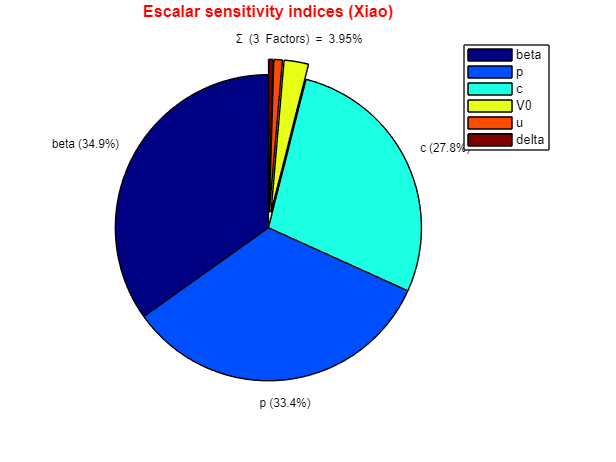

Operator '-' is not supported for operands of type 'string'.

Error in gsua_plot (line 218)
                    [c] = find( abs(t-tref(j)) <= min(abs(t-tref(j))) );

figure(1)
gsua_plot('Pie', Tsa, Tsa.STi, color = "summer")

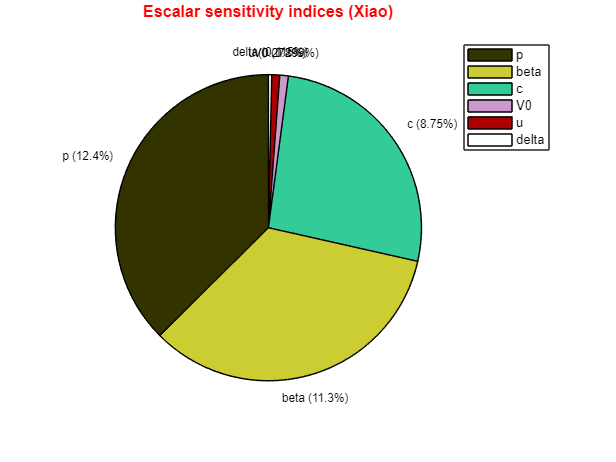

gsua_plot('Pie', Tsa, Tsa.Si)

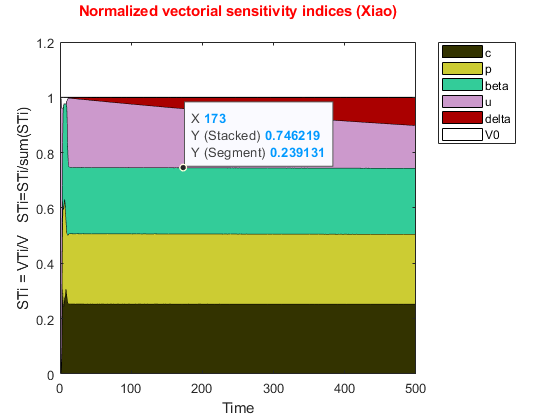

figure(3)
xdata = 0:500;
gsua_plot('TotalSensitivityArea', Tsa, Tsa.STi_vec, xdata)

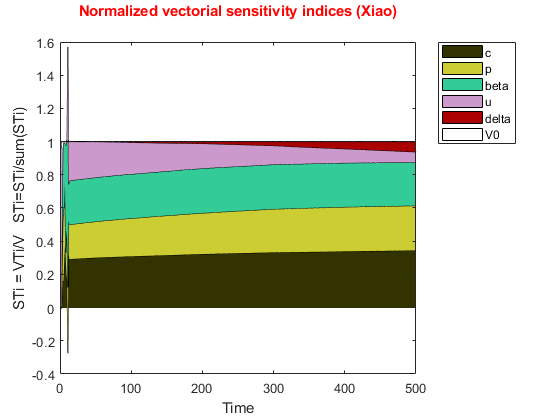

figure(4)
gsua_plot('TotalSensitivityArea', Tsa, Tsa.Si_vec, xdata)

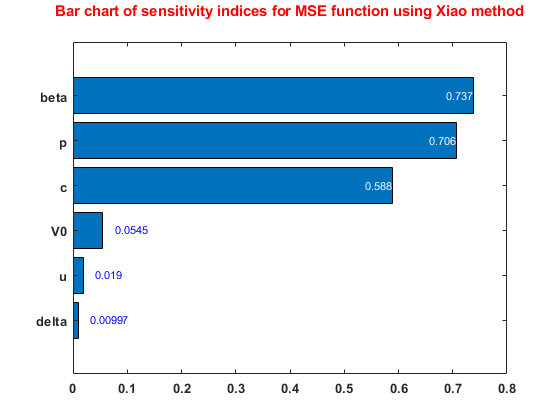

figure(5)
gsua_plot('Bar', Tsa, Tsa.STi)

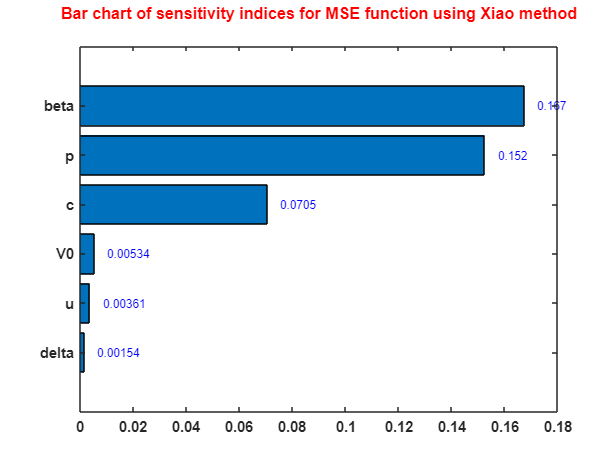

gsua_plot('Bar', Tsa, Tsa.Si)

### Analisis Sensibilidad con Control

clear all; clc
model='Simulink_EbolaControlMIMO';
ParIn={'Beta','C','Delta','P', 'U'}; 
Ranges=[1.52e-7 2.29e-7; 6.41 9.62;0.0008 0.0012;302.4 453.6; 400 600]; 
out_names={'Susceptible','Infected','Virus'};
[T,time] = gsua_dataprep(model,Ranges,ParIn,'out_names',out_names)

Setting environment to work with simulink
Setting nominal values
All done!


T = 5×2 table
                    Range             Nominal 
             ____________________    _________

    Beta     1.52e-07    2.29e-07    1.905e-07
    C            6.41        9.62        8.015
    Delta      0.0008      0.0012        0.001
    P           302.4       453.6          378
    U             400         600          500


time =          0    0.0448    0.1184    0.2001    0.2868    0.3825    0.4853    0.5286    0.5286    0.6314    1.0922    1.5508    1.5740    1.5740    1.6817    1.7895    1.8836    1.9873    2.0882    2.1025    2.1025    2.2034    2.6936    2.7086    2.7086    2.8321    2.9555    3.0000    3.0000    3.0000    3.1022    3.2045    3.2697    3.2697    3.3240    3.3240    3.3783    3.4326    3.5412    3.6631    3.7891    3.9162    4.0000    4.0000    4.0000    4.1271    4.2542    4.3910    4.5379    4.6848


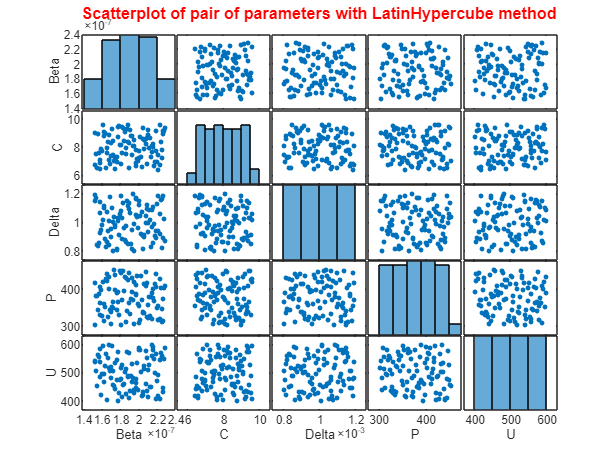

M = gsua_dmatrix(T, 100, 'Show', 'on');

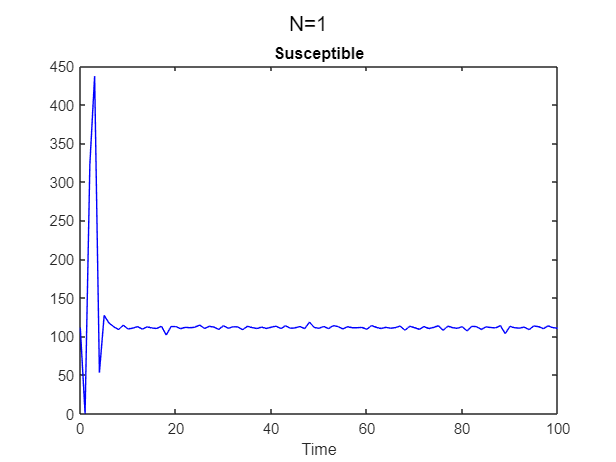

T.Properties.CustomProperties.output = 1;
ynom=gsua_eval(T.Nominal,T);

Tsa = gsua_sa(M, T, 'parallel', false,'SensMethod', 'Saltelli', 'ynom', ynom);

Progress: 15%
Estimated processing time (h:m:s): 0:1:31
Remaining time (h:m:s): 0:1:18
Elapsed time (h:m:s): 0:0:13
Estimated stop time (h:m:s): 20:45:4
Number of simulations: 455


Error using sens_montecarlo (line 91)
Simulation aborted

Error in gsua_pardeval (line 10)
    [y,~]=sens_montecarlo(Table2,M,xdata,parallel,init);

Error in 

Tsa

sum(Tsa.Si)/sum(abs(Tsa.Si))

ans = 0.6451

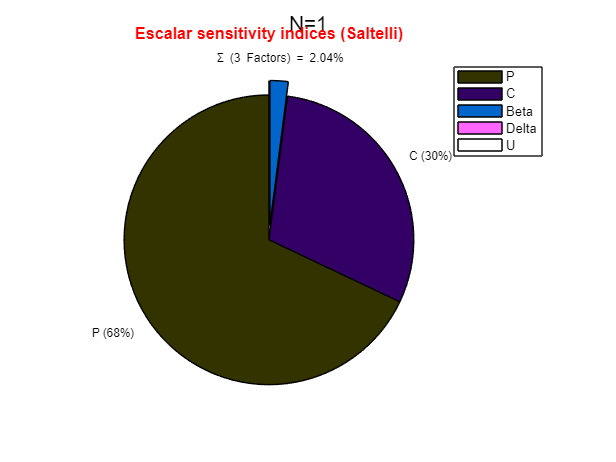

gsua_plot('Pie', Tsa, Tsa.STi)

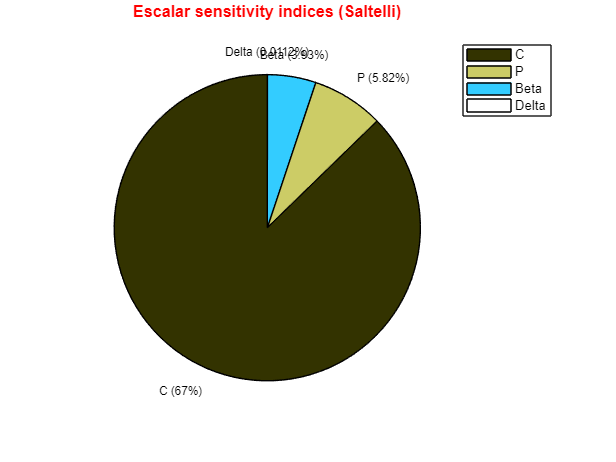

gsua_plot('Pie', Tsa, Tsa.Si)

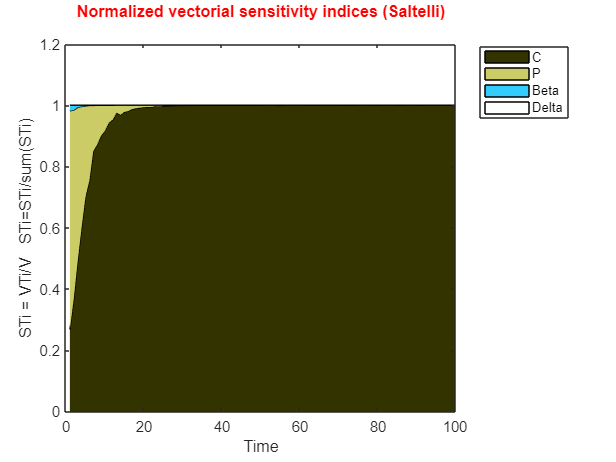

xdata = 0:100;
gsua_plot('TotalSensitivityArea', Tsa, Tsa.STi_vec, xdata)

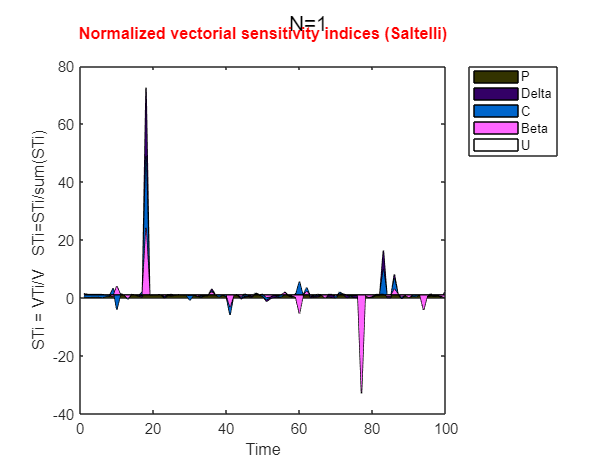

xdata = 0:100;
gsua_plot('TotalSensitivityArea', Tsa, Tsa.Si_vec, xdata)

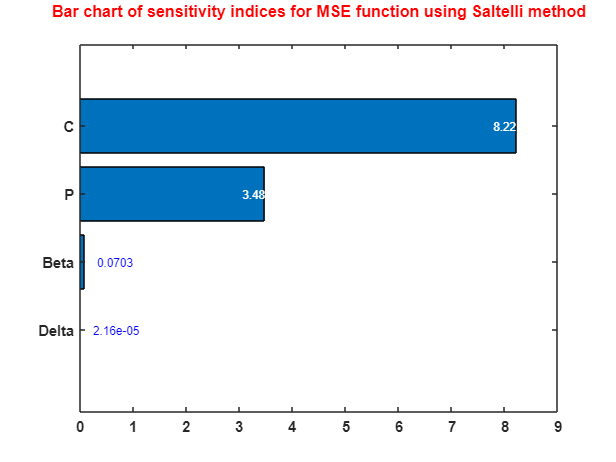

gsua_plot('Bar', Tsa, Tsa.STi)

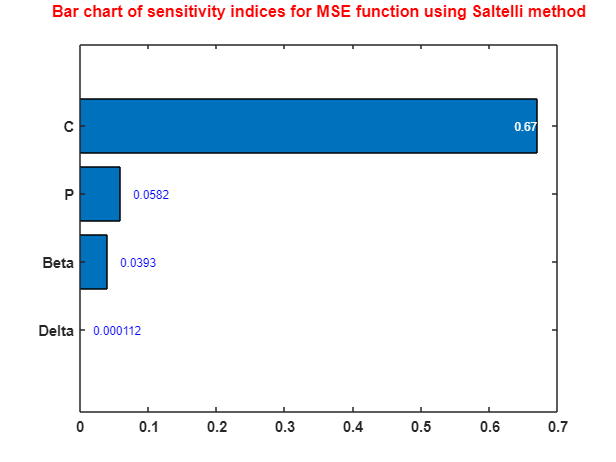

gsua_plot('Bar', Tsa, Tsa.Si)